Computes the balance resistor across each capacitor in a capacitor bank.

Computes the balance resistor based on the following source material:

[Source: CDM/CDE-Knowles, "Aluminum Electrolytic Capacitor Application Guide"](https://www.cde.com/resources/technical-papers/KNO_CD_AEappGuide_R2.pdf)

**Note this is simply the updated app note from CDE.**

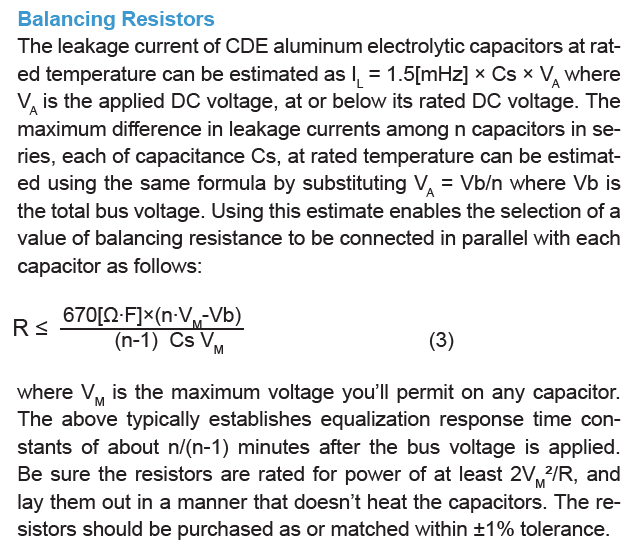

Vmax: max voltage allowed across each capacitor, V

Vbus: Max voltage across the entire series combination, V

C: Rated capacitance of each capacitor, F

n: Number of capacitors in series

R: Balance resistor value, Ohms

function R = computeBalanceResistor_v2(Vmax, Vbus, C, n)

% TODO: Implement the above equation

C_uf = C*1e6;   % Convert to uF
R = ((n*Vmax-Vbus)/(0.0015*C_uf*Vbus))*1e6;    % Compute balance resistor, conver to Ohm

end